% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% *** CAN ONLY DO 1 SESS at a time for PIX WISE ***

% load individual vars into group cell arrays
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh] = makeGroupStruct();

nGroup = 1


% if no pup data:
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of flurescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons

reigons =     'V1'    'LP-HVA'    'LA-HVA'    'MA-HVA'    'control'


cons4Legend

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


durs4Legend 

durs4Legend =     '6'


% LOCOMOTION - PERI STIM

durat = 1:length(uniqueDurations)

durat = 1

cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


state = 'loRun'

state = loRun

clear loBehState_onsetDf_allConsDurs
[loBehState_onsetDf_allConsDurs] = pixWiseByState(cont,durat,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,groupIdxStatTrials,groupIdxRunTrials,state,groupStimOnsetFrame,groupOnsetDf,groupBaselineIdx,nGroup,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);
sizeLoBehState_onsetDf_allConsDurs = size(loBehState_onsetDf_allConsDurs)

sizeLoBehState_onsetDf_allConsDurs =    108    99    15     7


state = 'hiRun'

state = hiRun

clear hiBehState_onsetDf_allConsDurs
[hiBehState_onsetDf_allConsDurs] = pixWiseByState(cont,durat,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,groupIdxStatTrials,groupIdxRunTrials,state,groupStimOnsetFrame,groupOnsetDf,groupBaselineIdx,nGroup,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);
sizeHiBehState_onsetDf_allConsDurs = size(hiBehState_onsetDf_allConsDurs)

sizeHiBehState_onsetDf_allConsDurs =    108    99    15     7


cont = 7

cont = 7

% SELECT RANGE for IMAGESC to SHOW PIX WISE PRE PERI-STIM FRAMES BASELINE
range = input('Fig 1: from 0-1, what range values to use? Enter in bracket form with low & high end values: ') % don't need to save range var out cuz don't need it in following functions/code, just display it 

range =          0    0.0500


colorMapOrNot = input('use colormap jet or no (yes = 1, no = 2)?: ')

colorMapOrNot = 1

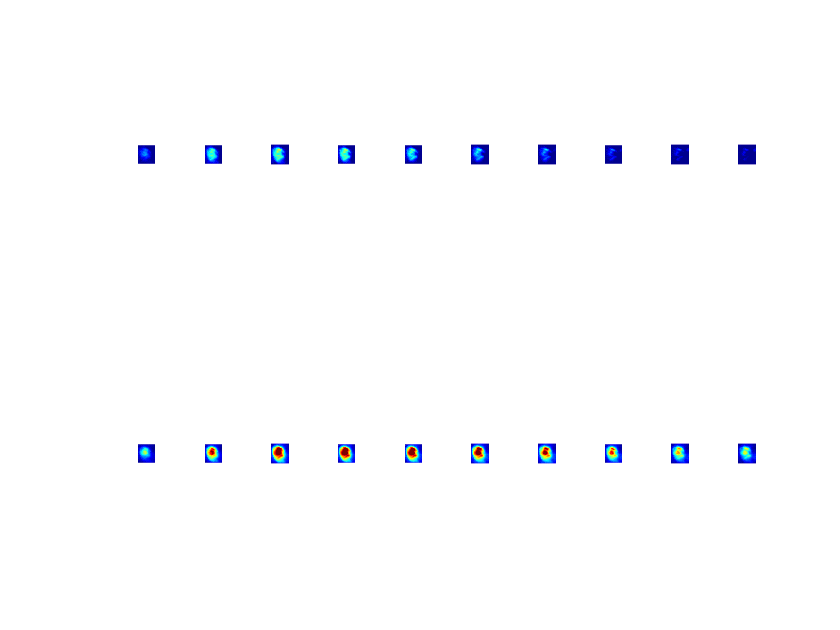

figure

for c = cont 
    
    clear f
    for f = groupStimOnsetFrame{1}+1:size(loBehState_onsetDf_allConsDurs,3)-1

        % plot each frame on own subplot
        subplot(2,size(loBehState_onsetDf_allConsDurs,3)-groupStimOnsetFrame{1}-1,f-groupStimOnsetFrame{1})
        imagesc(loBehState_onsetDf_allConsDurs(:,:,f,c),range) 
         
         if colorMapOrNot == 1
            colormap jet
         end 
    
         axis off;
         axis image;
         
    end % end f loop
    
    hold on 
       
    clear f
    for f = groupStimOnsetFrame{1}+1:size(loBehState_onsetDf_allConsDurs,3)-1
        
        lenColumns = length(groupStimOnsetFrame{1}+1:size(loBehState_onsetDf_allConsDurs,3)-1);
        
        % plot each frame on own subplot
        subplot(2,size(hiBehState_onsetDf_allConsDurs,3)-groupStimOnsetFrame{1}-1,(f-groupStimOnsetFrame{1})+lenColumns)
        imagesc(hiBehState_onsetDf_allConsDurs(:,:,f,c),range) 
         
         if colorMapOrNot == 1
            colormap jet
         end 
    
         axis off;
         axis image;
         
    end % end f loop
    
end % end c loop

% PUP - PERI STIM

durat = 1:length(uniqueDurations)

durat = 1

cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


state = 'loPup'

state = loPup

clear loBehState_onsetDf_allConsDurs
[loBehState_onsetDf_allConsDurs] = pixWiseByState(cont,durat,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,groupIdxStatTrials,groupIdxRunTrials,state,groupStimOnsetFrame,groupOnsetDf,groupBaselineIdx,nGroup,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);
sizeLoBehState_onsetDf_allConsDurs = size(loBehState_onsetDf_allConsDurs)

sizeLoBehState_onsetDf_allConsDurs =    108    99    15     7


state = 'hiPup'

state = hiPup

clear hiBehState_onsetDf_allConsDurs
[hiBehState_onsetDf_allConsDurs] = pixWiseByState(cont,durat,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,groupIdxStatTrials,groupIdxRunTrials,state,groupStimOnsetFrame,groupOnsetDf,groupBaselineIdx,nGroup,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);
sizeHiBehState_onsetDf_allConsDurs = size(hiBehState_onsetDf_allConsDurs)

sizeHiBehState_onsetDf_allConsDurs =    108    99    15     7


cont = 7

cont = 7

% SELECT RANGE for IMAGESC to SHOW PIX WISE PRE PERI-STIM FRAMES BASELINE
range = input('Fig 1: from 0-1, what range values to use? Enter in bracket form with low & high end values: ') % don't need to save range var out cuz don't need it in following functions/code, just display it 
colorMapOrNot = input('use colormap jet or no (yes = 1, no = 2)?: ')

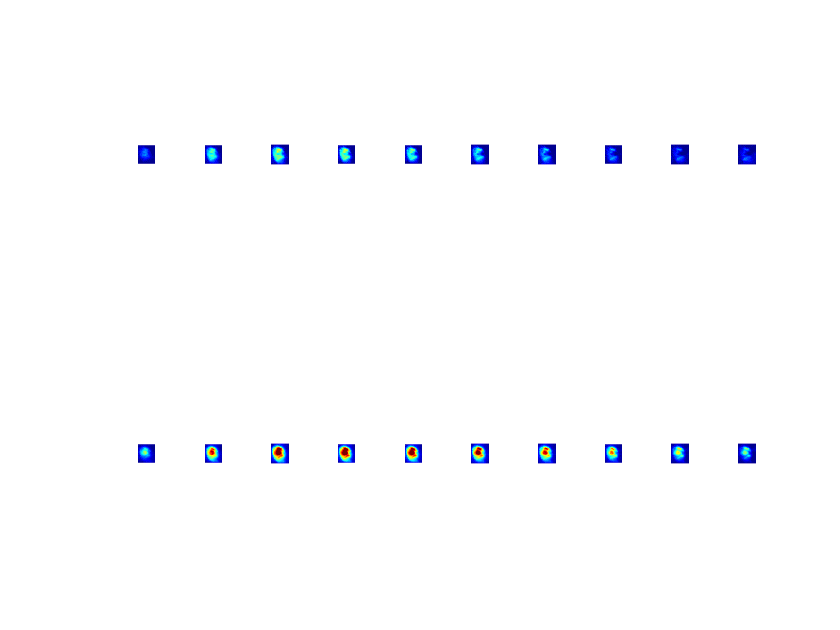

figure

for c = cont 
    
    clear f
    for f = groupStimOnsetFrame{1}+1:size(loBehState_onsetDf_allConsDurs,3)-1

        % plot each frame on own subplot
        subplot(2,size(loBehState_onsetDf_allConsDurs,3)-groupStimOnsetFrame{1}-1,f-groupStimOnsetFrame{1})
        imagesc(loBehState_onsetDf_allConsDurs(:,:,f,c),range) 
         
         if colorMapOrNot == 1
            colormap jet
         end 
    
         axis off;
         axis image;
         
    end % end f loop
    
    hold on 
       
    clear f
    for f = groupStimOnsetFrame{1}+1:size(loBehState_onsetDf_allConsDurs,3)-1
        
        lenColumns = length(groupStimOnsetFrame{1}+1:size(loBehState_onsetDf_allConsDurs,3)-1);
        
        % plot each frame on own subplot
        subplot(2,size(hiBehState_onsetDf_allConsDurs,3)-groupStimOnsetFrame{1}-1,(f-groupStimOnsetFrame{1})+lenColumns)
        imagesc(hiBehState_onsetDf_allConsDurs(:,:,f,c),range) 
         
         if colorMapOrNot == 1
            colormap jet
         end 
    
         axis off;
         axis image;
         
    end % end f loop
    
end % end c loop

% PIX WISE CRF by STATE

% which stimulus parameters to loop over:

durat = 1:length(uniqueDurations)

durat = 1

%durat = 1

cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 1;

%state = 'loRun'
%state = 'hiRun'
%state = 'loPup'
state = 'hiPup'

state = hiPup

%[allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupOnsetDf,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations)

clear pkPixWiseResp_CRF

% for each session
clear n
for n = 1:nGroup

    % EXTRACT list of stim params & stim conditions in order of trial 
    [durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);
    
    % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
    nthOnsetDf = groupOnsetDf{1,n};
    nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
    nthBaselineIdx = groupBaselineIdx{1,n}; 
    
    if state == 'loRun'
    
        % EXTRACT loRun TRIAL INDICIES
        nthIdxBehStateTrials = groupIdxStatTrials{1,n}; 
        
    end 
    
    if state == 'hiRun'
    
        % EXTRACT hiRun TRIAL INDICIES
        nthIdxBehStateTrials = groupIdxRunTrials{1,n}; 
        
    en
    
    if state == 'loPup'
    
        % EXTRACT hiRun TRIAL INDICIES
        nthIdxBehStateTrials = groupIdxSmallPupilTrials{1,n}; 
        
    end
    
    if state == 'hiPup'
    
        % EXTRACT hiRun TRIAL INDICIES
        nthIdxBehStateTrials = groupIdxLargePupilTrials{1,n}; 
        
    end
        
    % for each duration
    clear d
    for d = durat % at each duration
        
        % for each contrast
        clear c
        for c = cont 

            % SELECT TRIALS for specified pupil state & stim params
            clear idxTrials
            [idxTrials] = getTrials(conAndDurOrderedByTrialMeetCriteria,c,d,uniqueContrasts,uniqueDurations,nthIdxBehStateTrials);
           
            % INDEX PEAK FRAMES of SELECTED TRIALS in ONSET df, returns 
            % pix x pix x frames x trials
            clear dthCthTrialsPkFrames_nthOnsetDf
            dthCthTrialsPkFrames_nthOnsetDf = nthOnsetDf(:,:,nthPeakFrameIdx,idxTrials);
            nthOnsetDf_mnOverTrials = mean(dthCthTrialsPkFrames_nthOnsetDf,4);
            nthOnsetDf_mnOverTrialAndPkFrames = mean(nthOnsetDf_mnOverTrials,3);
            
            % CALCULATE MEAN BASELINE IMAGE  
            % get baseline frames, across all points, selected trials
            clear nthAllBaselineFrames
            nthAllBaselineFrames = nthOnsetDf(:,:,nthBaselineIdx,idxTrials);
            % take mean over frames for baseline frames of selected trials
            clear nthMnBaselineFrames
            nthMnBaselineFrames = mean(nthAllBaselineFrames,3); % 3rd dim is frames
            nthMnBaselineFrames = squeeze(nthMnBaselineFrames);
            % average over trials, get "mean baseline image"
            clear nthMnBaselineImage
            nthMnBaselineImage = mean(nthMnBaselineFrames,3);
     
            
            % do BASEline CORRECTION & COLLECT PEAK PIX WISE RESP at each CON
            % subtract the cth baseline from the flourescence at each c
            pkPixWiseResp_CRF(:,:,c) = nthOnsetDf_mnOverTrialAndPkFrames-nthMnBaselineImage;
            
            % record num trials fot these stim params/this state
            numTrials = length(idxTrials);
            %numTrialsEachCon_CRF(1,numTrials) = numTrials;

        end % end c loop   

    end % end d loop
    
end % end n loop

size_pkPixWiseResp_CRF = size(pkPixWiseResp_CRF)

size_pkPixWiseResp_CRF =    108    99     7



%loBehState_pkPixWiseResp_CRF = pkPixWiseResp_CRF;

%hiBehState_pkPixWiseResp_CRF = pkPixWiseResp_CRF;


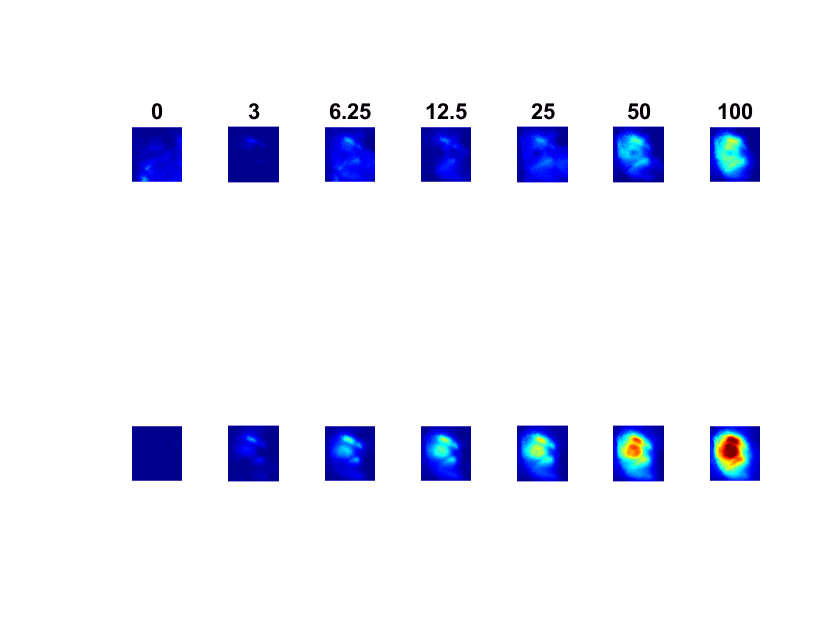

figure

for c = cont

    subplot(2,length(uniqueContrasts),c)
    imagesc(loBehState_pkPixWiseResp_CRF(:,:,c),range)
    
    title(cons4axes{c})
    
    if colorMapOrNot == 1
        colormap jet
    end 
    
    axis off;
    axis image;
    
end 

hold on 

for c = cont

    subplot(2,length(uniqueContrasts),c+7)
    imagesc(hiBehState_pkPixWiseResp_CRF(:,:,c),range)
    
    if colorMapOrNot == 1
        colormap jet
    end 
    
    axis off;
    axis image;
    
end 